% usuwanie wartosci skrajnych
%   [wart indx] = max(cond_sym(:,rozmiar));
%   iteracje_sym_bezprzes(indx,rozmiar) = 0;

% warunek stopu
%   while tol(fun(x)) > 0.00001 & i < 200+1

% % wyznaczanie pierw f. kwadratowej
% function [x1 x2] = pierw_f_kwadratowej(mala_macierz)
%     a = 1;
%     b = -(mala_macierz(1,1)+mala_macierz(2,2));
%     c = (mala_macierz(1,1)*mala_macierz(2,2))-(mala_macierz(2,1)*mala_macierz(1,2));
%     
%     x1 = (-b + sqrt(b*b - 4*a*c))/(2*a);
%     x2 = (-b - sqrt(b*b - 4*a*c))/(2*a);
%     if abs(x2) > abs(x1)
%         x1 = x2;
%     end
%    %drugi pierwiastek ze wzorów Viete'a
%     x2 = ((-b)/a) - x1;
% end

program

clc;
clear;
x = linspace(0,15,100);


ans = 8.2274

figure
y = fun(x);
plot(x,y,'b-',[0 15], [0 0], 'k--');
legend({'f(x)', 'y=0'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

**funkcje pomocnicze**

wyznaczenie wyjsc dla podanych x-ow i zadanej funkcji

function y = fun(x)
    [temp rozmiar_x] = size(x);
    y = zeros(rozmiar_x);
    y = y(:,1);
    for i = 1:rozmiar_x
        y(i,1) = 2.3*sin(x(1,i))+4*log(x(1,i)+2)-11;
    end
end

wyznaczenie wartosci zer na podstawie miejsc zerowych

function y = tol(x)
    y = max(abs(fun(x)));
end

funkcja wektoryzujaca macierz diagonalna

function w = wektor(A)
    rozmiar = size(A);
    for i = 1:rozmiar
        w(i,1) = A(i,i);
    end
end

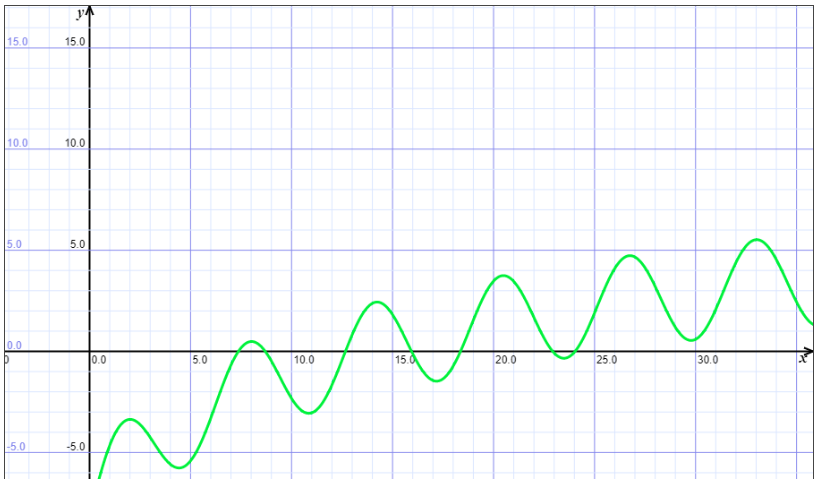

[https://www.matemaks.pl/program-do-rysowania-wykresow-funkcji.html](https://www.matemaks.pl/program-do-rysowania-wykresow-funkcji.html)

2,3*sin(x)+4*log(x+2)-11